clc;
clear;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 在真实场景 Dual-plane 中，
% 根据BESTAnP, Non-app, app 和 Combine_CIO算法的估计结果
% 画重投影图
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

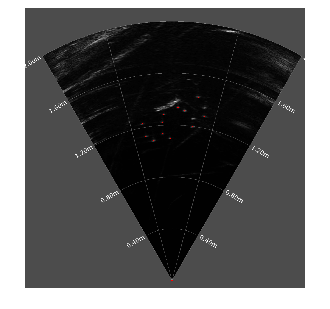

% 板子第七组数据
I=imread('C:\Users\Lenovo\Desktop\Matab Code\Experiments\reprojection experiments\15.png');
imshow(I)

p_si = [778	550
674	605
834	505
780	515
597	615
836	465
639	583
562	595
741	478
637	530
805	413
711	461
642	494
544	537
];



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 板子第七组数据
% ToCAnP AnP估计的坐标
p_si_est_my =[781.593597	550.7344774
665.4737679	604.0201466
836.7412596	502.7736661
784.6760111	513.8374625
587.4676403	616.9501061
840.0801846	465.8454653
631.8767369	584.1558793
552.8829521	596.4642006
741.1035225	478.516501
630.0281685	528.8646681
805.8843399	414.6166919
708.6975661	462.6817565
639.1373306	494.8387612
532.9168625	540.1274235

];

% Nonapp AnP估计的坐标
p_si_est_Nonapp = [774.0927477	570.2337325
670.8157579	642.7851596
831.1069068	530.9676304
777.810491	543.7565842
613.3261737	685.4356001
834.8877681	503.4074929
643.1719687	639.1282609
585.6661991	679.2533752
733.7296377	521.9481642
636.0416375	590.3631416
801.4535296	466.7786978
700.6188244	512.8300523
639.3665729	556.2366441
564.8592425	633.5287259
];

% App AnP估计的坐标
p_si_est_app = [ 779.1801828	549.6598903
665.0981072	603.0683164
833.0794213	501.3899137
782.5182302	512.8036938
591.5901565	615.2507222
836.4060913	464.4761314
633.3848292	583.0249971
559.7511981	594.0068598
740.356974	477.6392084
632.0330453	527.7096189
803.9938725	413.6253798
708.7777228	461.8057398
640.8475141	493.7485253
541.7914347	537.1788633
];

% CIO AnP估计的坐标
p_si_est_CIO = [ 782.8450303	550.555269
669.1182911	604.1521118
834.8834582	501.5764923
785.3029789	513.451582
594.0743132	616.3351431
837.3395796	464.4004291
636.6073796	584.0593997
561.4699234	595.1949695
742.9533565	478.3657599
634.9490047	528.7291248
804.2845372	413.5860064
711.5177368	462.6453689
643.7856164	494.7577357
542.8661507	538.453105
];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


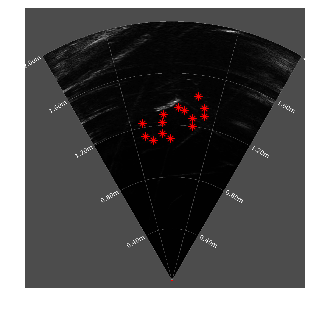

figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),15,'MarkerEdgeColor',[1,0,0],'Marker', '*');
xlabel('Ground Truth','FontSize', 30)

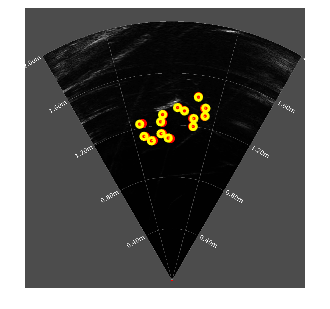


% ToCAnP AnP 绘制点到图像上 
figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),20,'MarkerEdgeColor',[1,0,0],'Marker', '*','LineWidth', 1.5);
scatter(p_si_est_my(:,1),p_si_est_my(:,2),10,'MarkerEdgeColor',[1,1,0],'Marker', 'o','LineWidth', 1.5);

% 遍历每对点，绘制连线
for i = 1:size(p_si, 1)
    plot([p_si_est_my(i, 1), p_si(i, 1)], [p_si_est_my(i, 2), p_si(i, 2)], 'y--'); % 连接对应点的线
end

% xlabel('Two-step AnP Algorithm','FontSize', 30)

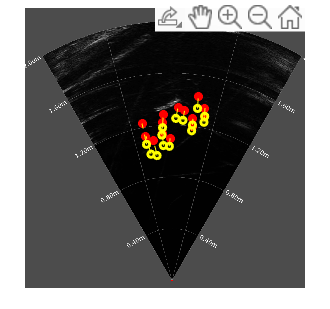

% Nonapp AnP 绘制点到图像上 
figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),20,'MarkerEdgeColor',[1,0,0],'Marker', '*','LineWidth', 1.5);
scatter(p_si_est_Nonapp(:,1),p_si_est_Nonapp(:,2),10,'MarkerEdgeColor',[1,1,0],'Marker', 'o','LineWidth', 1.5);

% 遍历每对点，绘制连线
for i = 1:size(p_si, 1)
    plot([p_si_est_Nonapp(i, 1), p_si(i, 1)], [p_si_est_Nonapp(i, 2), p_si(i, 2)], 'y--'); % 连接对应点的线
end

%xlabel('Non-app Algorithm','FontSize', 30)

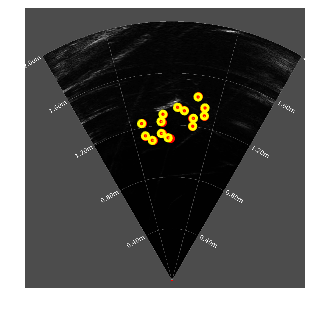

% App AnP 绘制点到图像上 
figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),20,'MarkerEdgeColor',[1,0,0],'Marker', '*','LineWidth', 1.5);
scatter(p_si_est_app(:,1),p_si_est_app(:,2),10,'MarkerEdgeColor',[1,1,0],'Marker', 'o','LineWidth', 1.5);

% 遍历每对点，绘制连线
for i = 1:size(p_si, 1)
    plot([p_si_est_app(i, 1), p_si(i, 1)], [p_si_est_app(i, 2), p_si(i, 2)], 'y--'); % 连接对应点的线
end

%xlabel('App Algorithm','FontSize', 30)

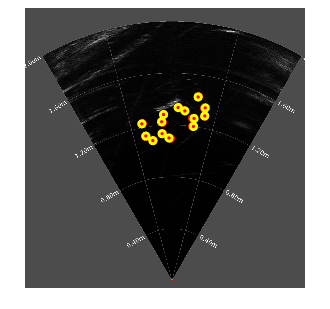

% CIO AnP 绘制点到图像上 
figure,imshow(I)
hold on; % 保持图像，以便叠加绘制
scatter(p_si(:,1),p_si(:,2),20,'MarkerEdgeColor',[1,0,0],'Marker', '*','LineWidth', 1.5);
scatter(p_si_est_CIO(:,1),p_si_est_CIO(:,2),10,'MarkerEdgeColor',[1,1,0],'Marker', 'o','LineWidth', 1.5);